# Lab 6

**Francesca Bennett**

**Physics 434**

**Collaborators: Taylor Prewitt, Natalie Shen**

clear all; close all;

%NOTE the difference in the pt size is the pt range

### **Problem 1**

To begin with, a background is created with a poisson distribtion. From this distribution, the first aim is to determine where the 5σ sensitivity threshold is. 

%OLD CODE :(
% figure(1);
% title("Comparison of QCD and Higgs, Data Rows 1 and 4")
% 
% h_H1=histogram(H1);
% set(h_H1,'FaceColor',"[0 0.392 0]");
% title("1: Higgs Pseudorapidity");

sig5=1/(3.5 * 10.^6);

%Sensitivity threshold:
S5=icdf('poisson',1-sig5,100)

S5 = 154

S5_lower=icdf('poisson',sig5,100)

S5_lower = 54

Here, we take the inverse cdf to the upper and lower bounds of 5σ to find the corresponding sensitivity threshold for our generated poisson distribution.

### **Problem 2**

Now create a set of injected (simulated) signals of a single strength. You will want to make your signal moderately strong, say somewhere in the 8-30 σ range. Inject this signal into your background data many times.

Background has lambda=100

Background is extremely unlikely to ever fluctuate to say 14 sigma, so choose something greater than 190 because the signal chosen should be greater than such as 8 sigma, and 8 sigma of the signal is 190

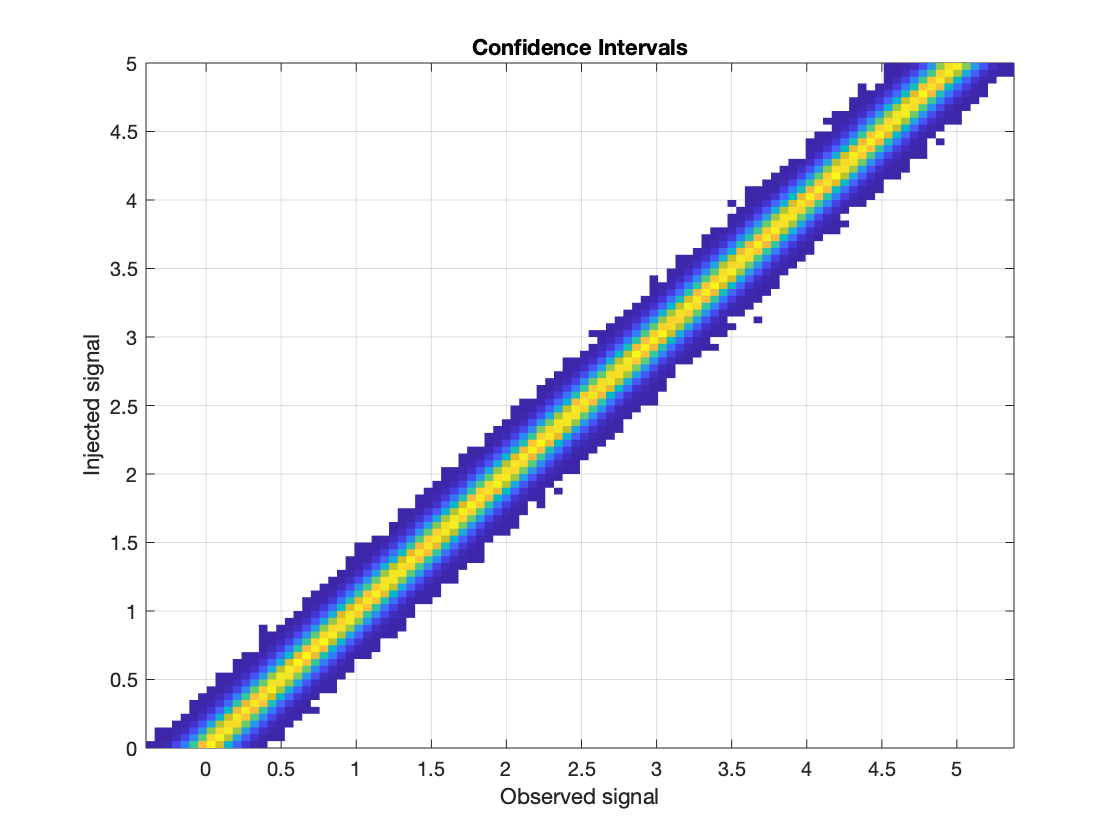

%********
sig15=3*(10^(-17));

%Sensitivity threshold:
S15=icdf('poisson',1-sig15,100);

size = 1000;
N = randn(size,size)*0.1;
%SigStrength = [1:1000];

SigStrength = linspace(0,5,1000);
[input1, signal] = meshgrid(SigStrength);

Observed = N + signal;

figure()
h = histogram2(Observed,signal,100,'DisplayStyle','tile','ShowEmptyBins','off');
ylabel("Injected signal")
xlabel("Observed signal")
title("Confidence Intervals")


figure()
index = 300;
s=signal(index)

s = 1.4965

**Part 2.A**

 Histogram how **bright ***(number of events)* the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.

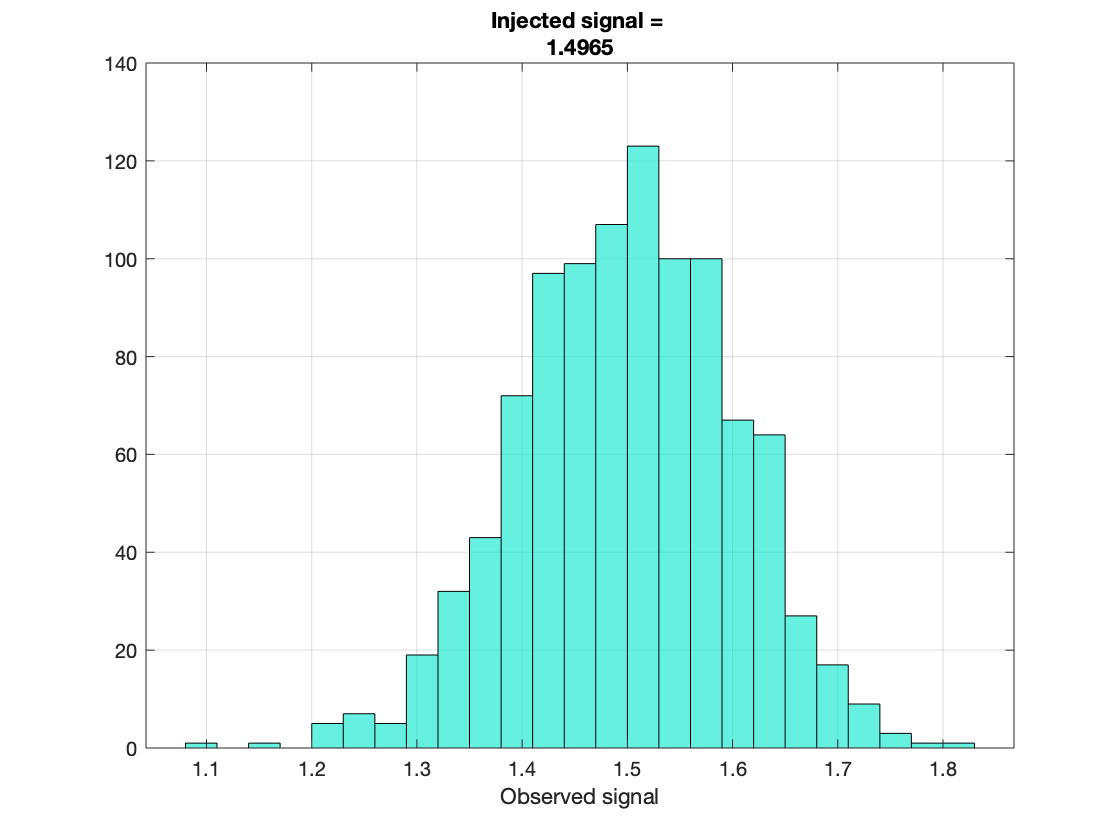

h1=histogram(Observed(index,:),25);
%xlim([-0.2 5.1]);
set(h1,'FaceColor',"[0 0.9 0.8]");
grid on
title(["Injected signal = ", num2str(signal(index))]);
xlabel("Observed signal");

**Part 2.B**

b) Is your observed signal biased? (e.g. is the observed value equally likely to be stronger or weaker than the true injected signal?) Is it symmetric?

If 1=1 not biased, or if 1=3 biased

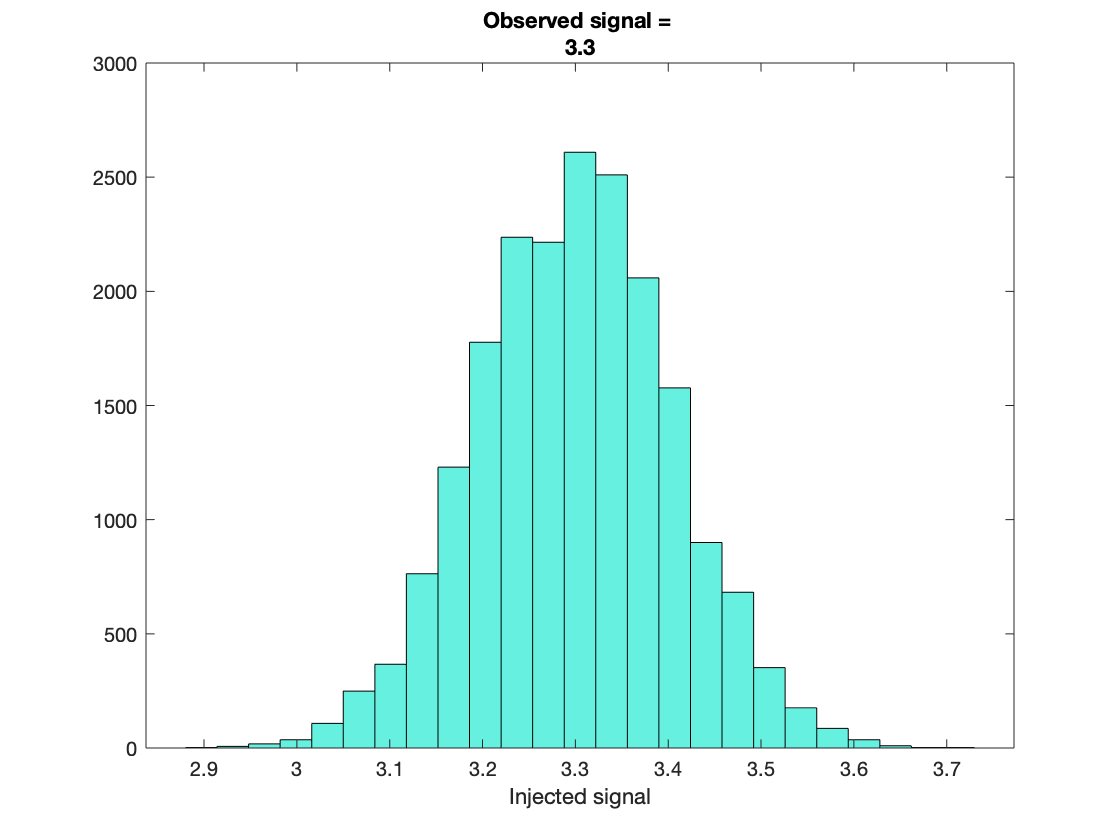

observation=3.3;

injected = signal(abs(Observed - observation)<0.05);
h2=histogram(injected,25);
%xlim([-0.2 5.1]);

title(["Observed signal = ", num2str(observation)]);
xlabel("Injected signal");
set(h2,'FaceColor',"[0 0.9 0.8]");

Because the line for the data does not follow a model of y=x, instead shifted so that y=mx, where m is some multiplier on x, it indicates that the data is biased.

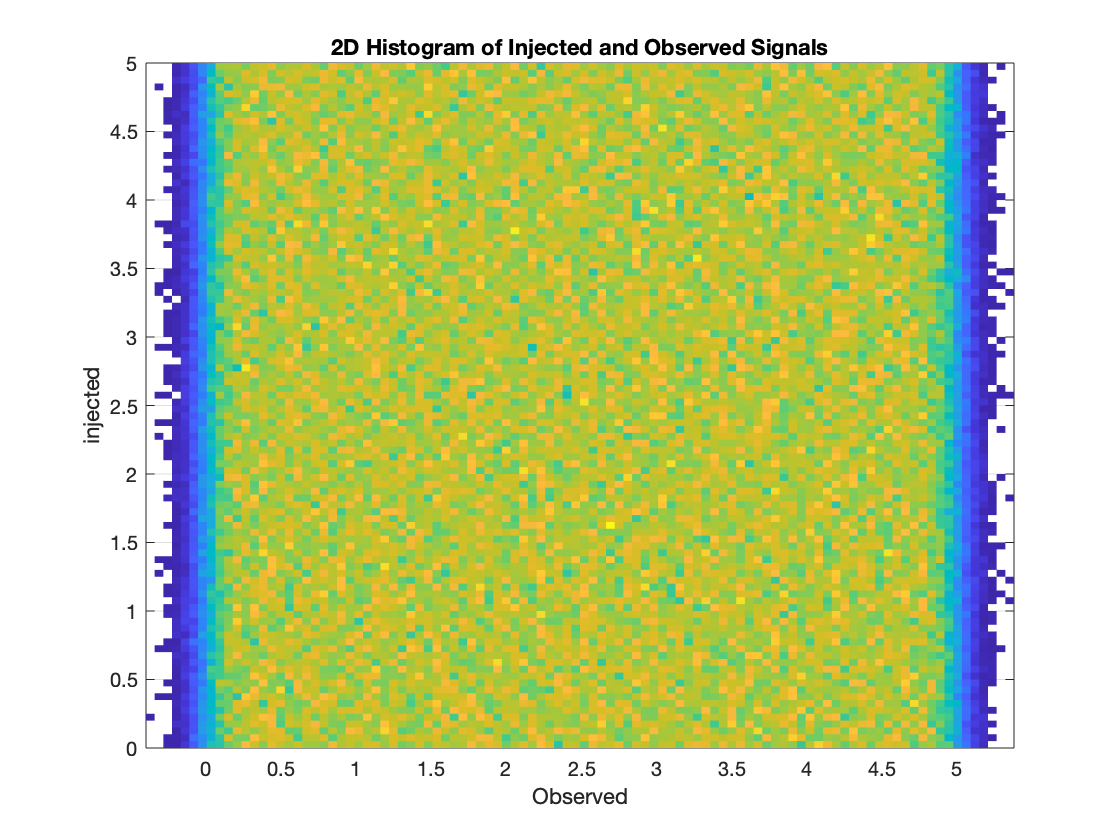

injected1=[injected(1:1:1000)];
histogram2(Observed, input1,100,'DisplayStyle','tile','ShowEmptyBins','off')
title('2D Histogram of Injected and Observed Signals')
xlabel('Observed')
ylabel('injected')

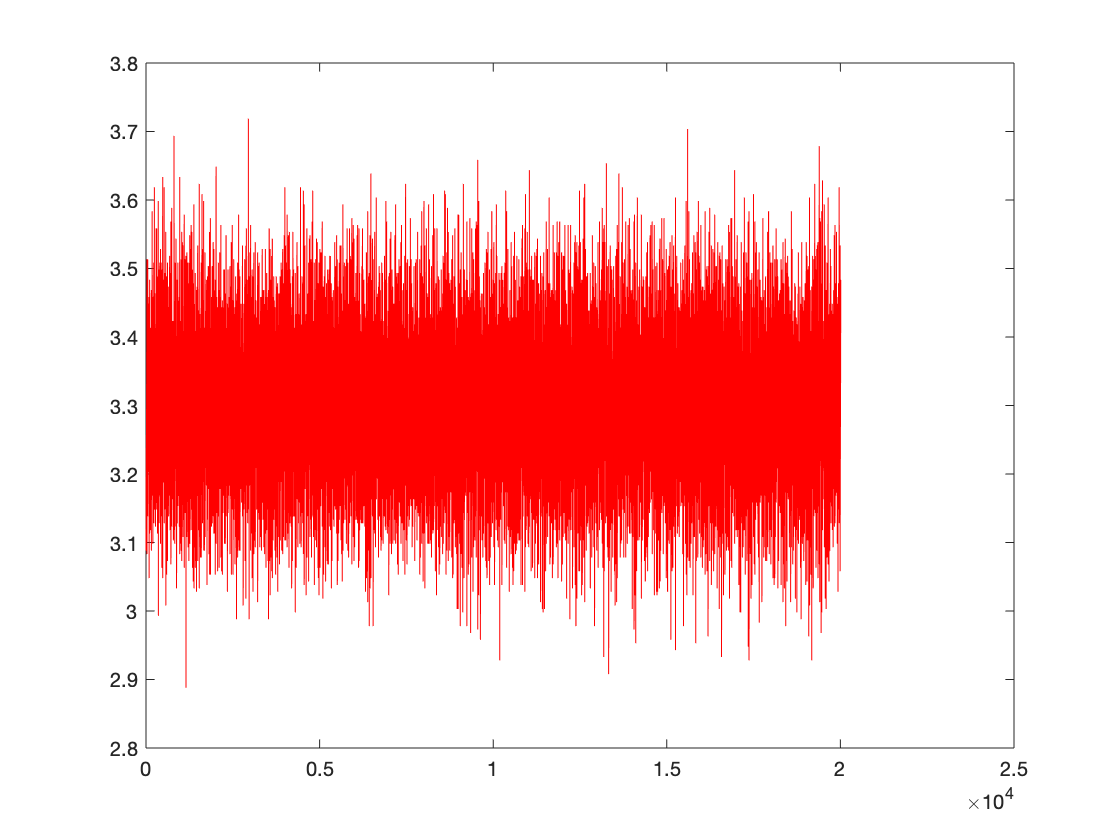


plot(injected,"red");

The data is also interpreted to be symmetric because the dispersion of the count intensity, as seen on the 2D histogram, is not symmetrical around the y=mx line, with more activity seen on the upper side of the line.

### **Problem 3**

Continuing from Problems 1 and 2, we will make a "suite" of injected signals with various strengths, ranging from zero to more than 10σ.

*Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ*

* (30σ or more). *

**Part 3.A**

The statement of what we intend to simulate is as follows:

*Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed signal*

**We have our determined true signal, but what is the range of signals we could see?**

Below is the 2D plot of the observed signal vs. the normal data.

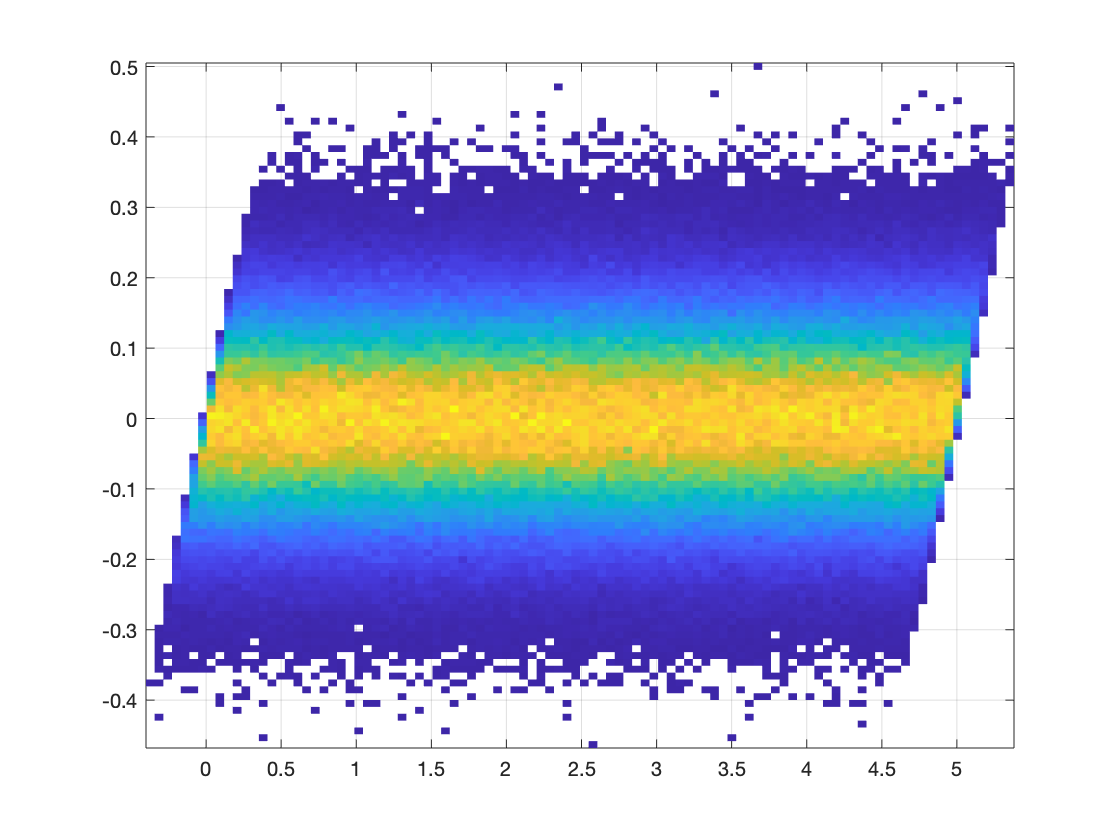

histogram2(Observed,N,100,'DisplayStyle','tile','ShowEmptyBins','off')

**Part 3.B**

To show that the same injected signal power was achieved for both Problem 2's injected signal and this problem's injected signal, we use the following method:

*If you choose the same injected signal power as in problem 2, show that you get the same answer.*

**Part 3.C**

Below is a histogram of a chosen observed signal () and the injected signal pdf.

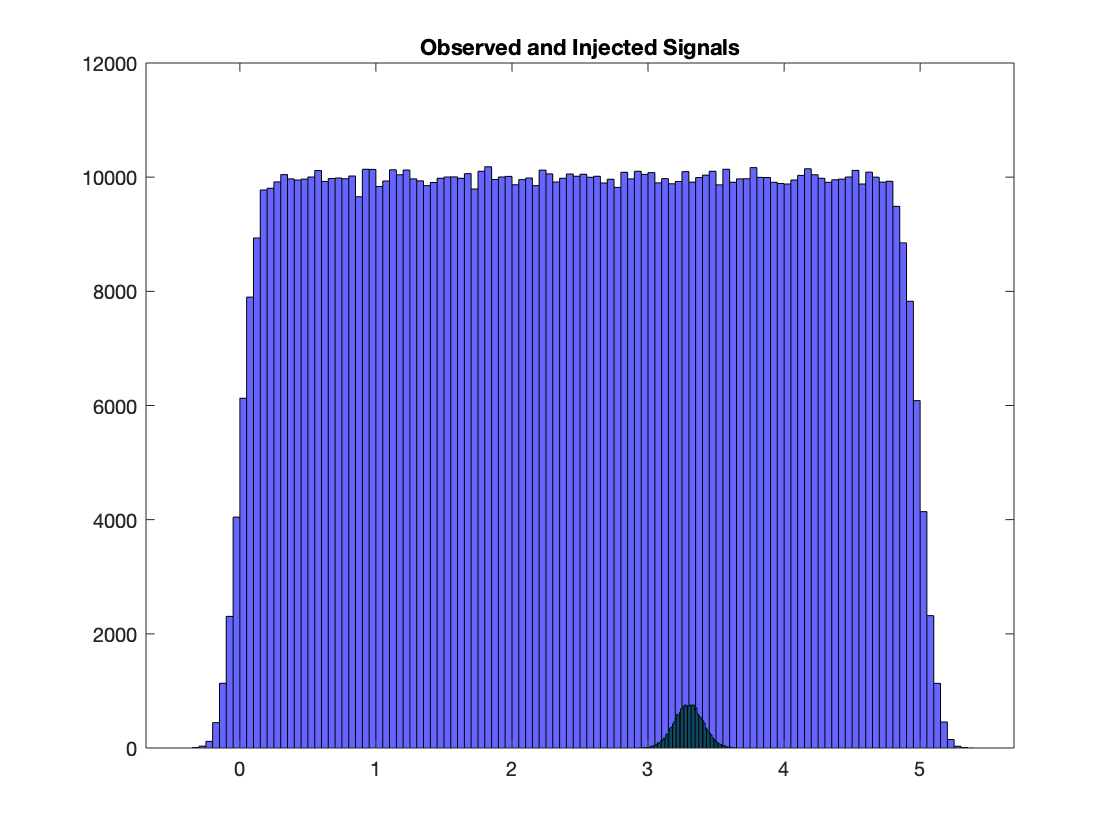

histogram(Observed,'FaceColor',"blue")
title("Observed and Injected Signals")
hold on
histogram(injected,'FaceColor',"cyan")
hold off

The histogram shows that the injected signal has a much more decreased range than the observed signal, and that it is also much lower in magnitude.

*Now reverse the problem, select an observed signal (pick something quite a bit stronger than 5σ) and create a 1D histogram of the injected signal pdf(). Describe the meaning of this histogram.*

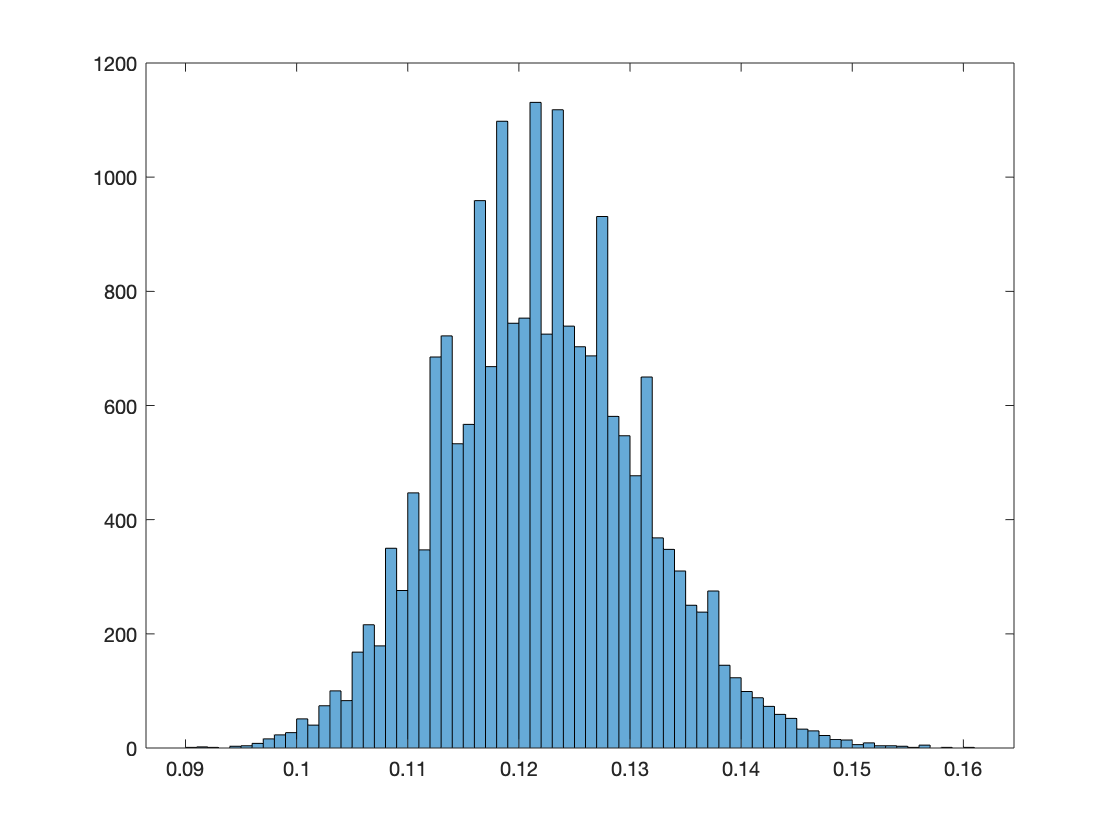

new=pdf('poiss',1,injected);
histogram(new)

This histogram shows the pdf of the injected signal fit to a Poisson distribution. Most of the injected signal fits well, but some of the points are outliers.

**Part 3.D**

For the observed signal, the 1σ uncertainty on the true signal strength is:

 For your observed signal, what is the 1σ uncertainty on the true signal strength?

**Part 3.E**

* Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?*

A poisson distribution is not symmetric , therefore our answer is not symmetirc. The distribution is close to being symmetric, since for any large n a distribution approaches the gaussian which is symmetric, but currently this distribution is still not symmetric.

*Is it biased? Does this make sense?*

This distribution is  biased.

#### **Problem 4**

With the same setup as Problem 3, a weak signal is now used:

*Using the same setup as in problem 3, now pick a relatively weak signal (say in the 1σ range, exact strength not important).*

**Part 4.A**

Repeating the procedure in Part 3.C, the injected signal pdf is calculated.

 It is shown that the pdf extends to zero.

*Repeat problem 3c, calculating the injected signal pdf(). One of the differences you should immediately see is that the pdf() extends to zero.*

**Part 4.B**

The pdf of the inject signal extends to zero because...

**Describe what it means to have the true signal pdf() extend to zero.**

**Part 4.C**

c) Calculate a 95% confidence upper bound. [Hints: make sure your pdf() is normalized. The statistical question is: if I observe this candidate signal (and it is too weak to claim a detection), then the true signal would be less than X 95% of the time.]